En este codigo, resolveremos el problema 7.3 del libro de scientist computing with matlab a traves de dos algoritmos, uno simbolico y otro númerico. Primero lo resolvemos de forma simbolica.

El sistema propuesto es:


$$x\prime \prime (t) + 5 x \prime + 4x + 3y = e^{-6t} \sin(4t)$$
  


$$2y\prime + y + 4x\prime + 6x = e^{-6t} \cos(4t)$$


Con las condiciones


$$x(0) = 1, \;\;\;\; x(\pi)=2, \;\;\;\; y(0)=0$$


Iniciamos definiendo las variables y escribiendo las ecuaciones diferenciales

syms x(t) y(t) t
ec1 = diff(x,t,2) + 5*diff(x,t,1) + 4*x + 3*y == exp(-6*t)*sin(4*t)

$$ec1(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+5\,\frac{\partial }{\partial t}x\left(t\right)+4\,x\left(t\right)+3\,y\left(t\right)=\sin\left(4\,t\right)\,{\mathrm{e}}^{-6\,t}$$

ec2= 2*diff(y,t,1) + y + 4*diff(x,t,1) + 6*x == exp(-6*t)*cos(4*t)

$$ec2(t) = 6\,x\left(t\right)+y\left(t\right)+4\,\frac{\partial }{\partial t}x\left(t\right)+2\,\frac{\partial }{\partial t}y\left(t\right)=\cos\left(4\,t\right)\,{\mathrm{e}}^{-6\,t}$$

ec=[ec1,ec2];

Guardamos las eucaciones como un vector, ahora introducimos todas las condiciones iniciales que tenemos

cond=[x(0)==1, x(pi)==2, y(0)==0];

Finalmente resolvemos con la información obtenida:

[x,y]=dsolve(ec,cond)

Ahora vamos a graficar la solución

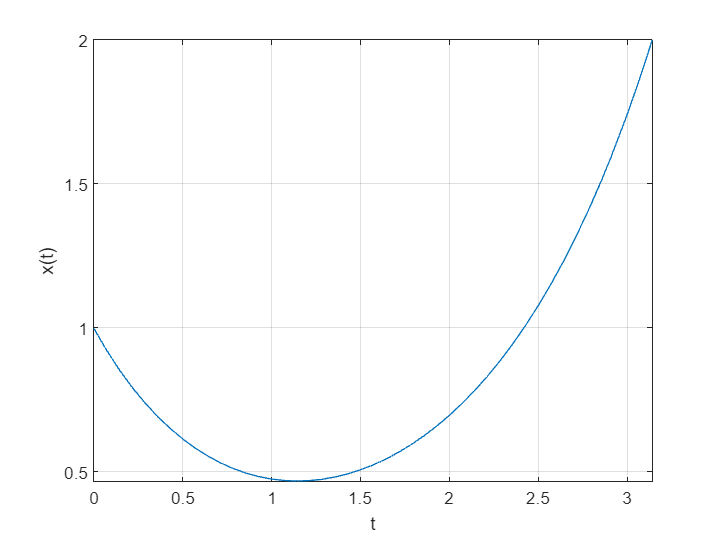

figure
fplot(x,[0 pi]), grid, xlabel('t'), ylabel('x(t)')

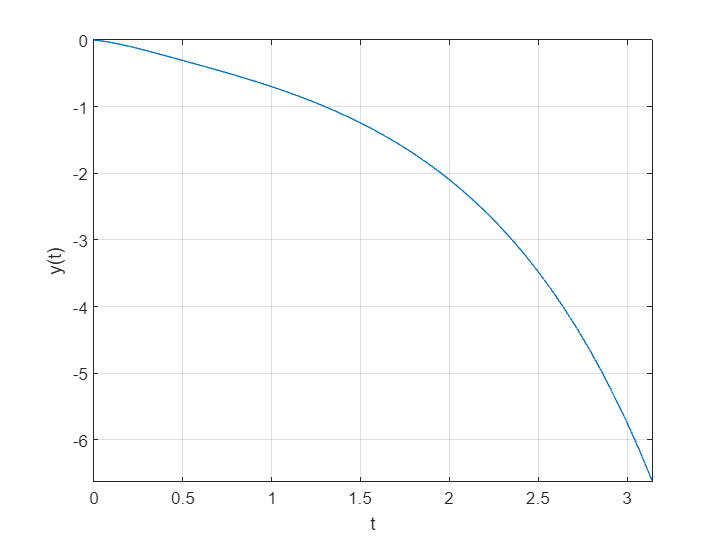

figure
fplot(y,[0 pi]), grid, xlabel('t'), ylabel('y(t)')

Estas son las soluciones analiticas y exactas.

Ahora haremos la solución de forma númerica. Configuramos nuestras variables de estado de la siguiente forma

El sistema propuesto es:


$$x\prime \prime (t) + 5 x \prime + 4x + 3y = e^{-6t} \sin(4t)$$
  


$$2y\prime + y + 4x\prime + 6x = e^{-6t} \cos(4t)$$


Con las condiciones


$$x(0) = 1, \;\;\;\; x(\pi)=2, \;\;\;\; y(0)=0$$


Definimos las variables de estado como


$$x=x(1), \;\;\; x\prime=x(2)
$$
 


$$y=x(3)$$


Entonces, introducimos las funciones. Notemos lo siguiente, tenemos un vector columnas, con 3 entradas, estan representan lo siguiente:

- La primera entrada representa la derivada de x(1), en este caso, como no podemos despejar la derivada de x(1), la cual es x(2), ponemos x(1)

- La segunda entrada representa la derivada de x(2), en este caso es la derivida de orden mayor que podemos despejar de la primera ecuacion de nuestro sistema, la cual colocamos ahi

- La tercera entrada representa la derivada de x(3), que en este caso es la derivada de y(t) y la despejamos de la segunda ecuacion de nuestro sistema.

f1=@(t,x)[x(2);exp(-6*t)*sin(4*t)-5*x(2)-4*x(1)-3*x(3);(1/2)*(exp(-6*t)*cos(4*t)-x(3)-4*x(2)-6*x(1))]

f1 = function_handle with value:
    @(t,x)[x(2);exp(-6*t)*sin(4*t)-5*x(2)-4*x(1)-3*x(3);(1/2)*(exp(-6*t)*cos(4*t)-x(3)-4*x(2)-6*x(1))]


Ahora ponemos las condiciones a la frontera

Para esto, creamos una funcion handle donde $ya$ representa las condiciones iniciales, en este caso $ya(1)-1$ representa la condicion $x(0)=1$ y $ya(2)$ representa la condicion $y(0)=0$, finalmente y $yb(1)$ representa $x(\pi)$

g1=@(ya,yb)[ya(1)-1;ya(2);yb(1)-2]

g1 = function_handle with value:
    @(ya,yb)[ya(1)-1;ya(2);yb(1)-2]


El vector x1 dentro del algoritmo que vamos a utilizar representa las condiones iniciales de $x(1), x(2), x(3)$ respectivamente. Como no sabemos cual es la condicion inicial de $x(2)$ introducimos un valor aleatorio

x1=[1;rand(1);0]

x1 =     1.0000
    0.0344
         0


Aqui creamos el inicializador. La primera entrada representa nuestro rango de valores de t y la seguna representa los valores con los que inicia el codigo

sinit=bvpinit(linspace(0,pi,32),x1)

sinit = struct with fields:
    solver: 'bvpinit'
         x: [0 0.1013 0.2027 0.3040 0.4054 0.5067 0.6081 0.7094 0.8107 0.9121 1.0134 1.1148 1.2161 1.3174 1.4188 1.5201 1.6215 1.7228 1.8242 1.9255 2.0268 2.1282 2.2295 2.3309 2.4322 2.5335 2.6349 2.7362 2.8376 2.9389 3.0403 3.1416]
         y: [3×32 double]
     yinit: [3×1 double]


Ahora calculamos la solución usando el algoritmo bvp5c

S=bvp5c(f1,g1,sinit)

S = struct with fields:
    solver: 'bvp5c'
         x: [0 0.1013 0.2027 0.3040 0.4054 0.5067 0.6081 0.7094 0.8107 0.9121 1.0134 1.1148 1.2161 1.3174 1.4188 1.5201 1.6215 1.7228 1.8242 1.9255 2.0268 2.1282 2.2295 2.3309 2.4322 2.5335 2.6349 2.7362 2.8376 2.9389 3.0403 3.1416]
         y: [3×32 double]
     idata: [1×1 struct]
     stats: [1×1 struct]


FInalmente graficamos la solucion

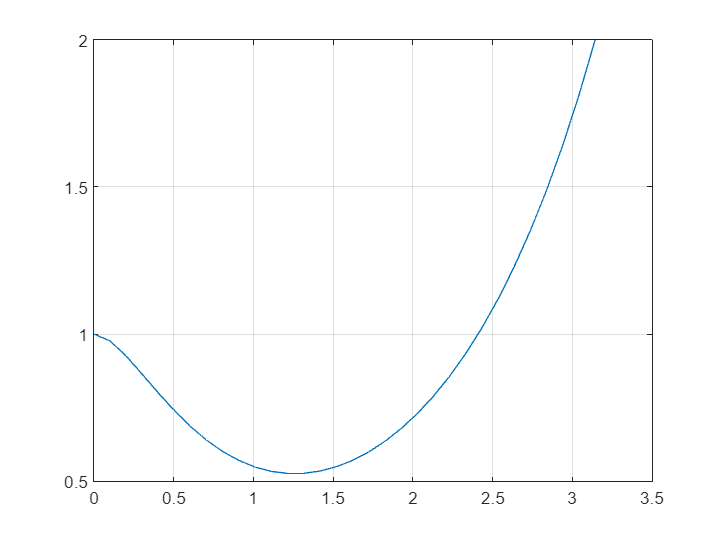

figure
plot(S.x,S.y(1,:)), grid

Graficamos

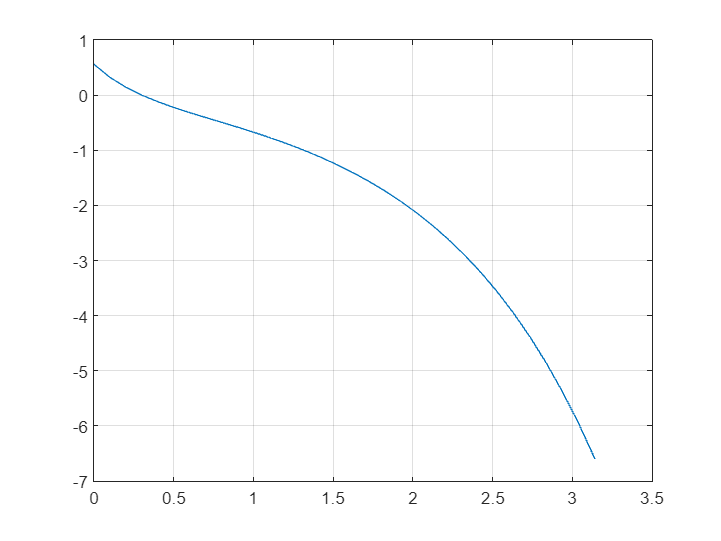

figure
plot(S.x,S.y(3,:)), grid

Introduce la funcion, y las condiciones a la frontera:

f=@(t,x,v)[4*x(1)+v(1)*x(1)*x(2); -2*x(2)+v(2)*x(1)*x(2)]

f = function_handle with value:
    @(t,x,v)[4*x(1)+v(1)*x(1)*x(2);-2*x(2)+v(2)*x(1)*x(2)]


g=@(ya,yb,v)[ya(1)-2; ya(2)-1; yb(1)-4; yb(2)-2] % boundaries

g = function_handle with value:
    @(ya,yb,v)[ya(1)-2;ya(2)-1;yb(1)-4;yb(2)-2]


x1=[1;1]; x2=[-1;2]; sinit=bvpinit(linspace(0,3,20),x1,x2)

sinit = struct with fields:
        solver: 'bvpinit'
             x: [0 0.1579 0.3158 0.4737 0.6316 0.7895 0.9474 1.1053 1.2632 1.4211 1.5789 1.7368 1.8947 2.0526 2.2105 2.3684 2.5263 2.6842 2.8421 3]
             y: [2×20 double]
    parameters: [2×1 double]
         yinit: [2×1 double]


options=bvpset; options.RelTol=1e-8; S=bvp5c(f,g,sinit,options)

S = struct with fields:
        solver: 'bvp5c'
    parameters: [2×1 double]
             x: [0 0.0526 0.1053 0.1579 0.2105 0.2632 0.3158 0.3684 0.4079 0.4474 0.4868 0.5263 0.5658 0.6053 0.6447 0.6842 0.7237 0.7632 0.7895 0.8158 0.8421 0.8684 0.9079 0.9474 0.9868 1.0263 1.0658 1.1053 1.1447 1.1842 1.2237 1.2632 1.3026 1.3421 … ]
             y: [2×64 double]
         idata: [1×1 struct]
         stats: [1×1 struct]


S.parameters % show undermined parameters

ans =    -2.3721
    0.8934


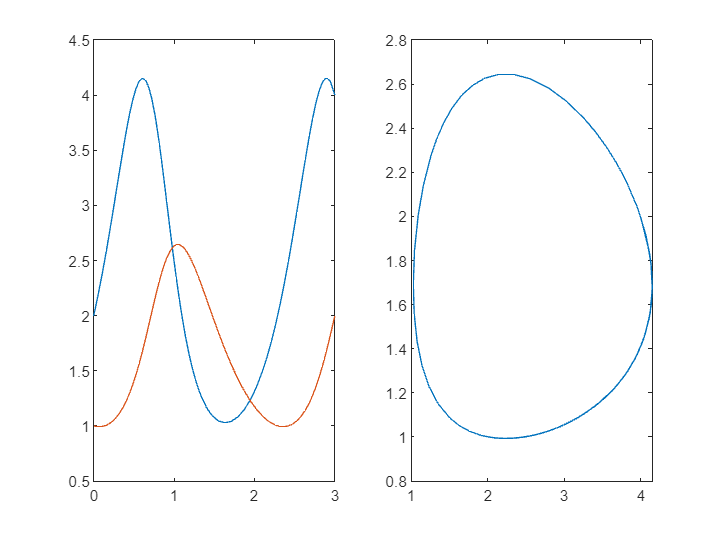

subplot(121), plot(S.x,S.y); subplot(122), plot(S.y(1,:),S.y(2,:));